# Figure S6A

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';
load([dataDir filesep 'A050_data.mat'],'S','settings','allIF');
conditions = settings.conditions


framesPerHr = 60/12;
 frameDrugAdded =37;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
   
    for n = 1:length(dat.POI(:,1))
       if dat.POI(n,1) + round(.5*framesPerHr) <= numFrames & dat.POI(n,1) > 1 * framesPerHr
            apcExpressGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(.5*framesPerHr)) < .1 & ...
               dat.apcNormM(n,dat.POI(n,1) - 1 * framesPerHr) > .5 ;
       end
     
    end
    S(i).apcExpressGate = apcExpressGate;
       

end

S6A

conds=[2 8 10 ];

colors = [.1 .4 1;.6 .1 .5;.7 .7 .2;.8 .9 .4;.3 1 .5];
clear cols
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 50];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
      inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,1)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
 sum(inds)


    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    yvals = yvals(yvals < 2000 & yvals >= 0);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 5113

ans = 1068

ans = 1779

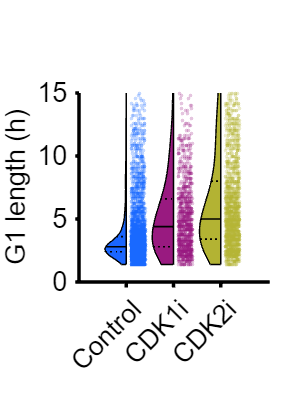


figure('Units', 'Inches', 'Position', [0, 0, 3, 4])

h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 5,groupcol(groups,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'G1 length (h)'])


xticklabels({'Control','CDK1i','CDK2i','CDC7i','siCyclinE1/2 + CDC7i'})
ylim([0 15])
 xtickangle(45)
axis square




p=mediantest(ally(groups==1),ally(groups==2))

p = 2.1832e-80

% print_pdf(['fig_S6A.svg'])